# Harmonic Oscillator

The system is defined by the following second-order differential equation,


$$\ddot{x} + \gamma \dot{x} + x = 0$$



$$\text{Now, let } y = \dot{x}
$$



$$\text{Then } \dot{y} = -x - \gamma y$$



$${(}\matrix{{\dot{x}} \cr {\dot{y}}})=(\matrix{0 & 1 \cr -1 & -\gamma})(\matrix{x\cr y})$$


## Parameters

Linear 2D system.

gamma_vals = 0.2:0.2:2.4;
A = [0 1; -1 0];   % matrix defined, where x'_vec = A.x_vec is the system.

Solve the equation using ODE45.

clf;
f = figure; hold on;

% iterate over values of gamma; set gamma in A each time.
for gamma_idx=1:length(gamma_vals)
    
    % define the equation.
    A(2,2) = -1 * gamma_vals(gamma_idx);
    dx = @(t, x)[A(1,1)*x(1) + A(1,2)*x(2); A(2,1)*x(1) + A(2,2)*x(2)];

    % set the starting points to be along the unit circle
    x_start = cos([0:2*pi/8:2*pi]);
    y_start = sin([0:2*pi/8:2*pi]);
    
    subplot(4, 3, gamma_idx);
    
    plot([-1 1],[0 0],'k:'); hold on;       %initial x axis (dotted)
    plot([0 0],[-1 1],'k:'); hold on;       %initial y axis (dotted)
    
    % axis square
    xlabel('x');
    ylabel('y');
    title(['gamma = ' num2str(A(2,2))]);
    
    m1=0;   
    for ii=1:length(x_start)
        [tout, x] = ode45(dx, [0 100], [x_start(ii); y_start(ii)]);     % starting points on a circle
        plot(x_start(ii), y_start(ii), 'ro'); hold on;                  % plot the starting points in red
        plot(x(:,1), x(:,2), 'b-'); hold on;
    end  
end

## Now plot the vector field

clf;
f = figure; hold on;
f.Position(3:4) = [3000 3000]

f =   Figure (27) with properties:

      Number: 27
        Name: ''
       Color: [1 1 1]
    Position: [584 495 3000 3000]
       Units: 'pixels'

  Use GET to show all properties



get(f)

                 Alphamap: [0 0.0159 0.0317 0.0476 0.0635 0.0794 0.0952 0.1111 0.1270 0.1429 0.1587 0.1746 0.1905 0.2063 0.2222 0.2381 0.2540 0.2698 0.2857 0.3016 0.3175 0.3333 0.3492 0.3651 0.3810 0.3968 0.4127 0.4286 0.4444 0.4603 ... ] (1x64 double)
             BeingDeleted: off
               BusyAction: 'queue'
            ButtonDownFcn: ''
                 Children: [1x1 Axes]
                 Clipping: on
          CloseRequestFcn: 'closereq'
                    Color: [1 1 1]
                 Colormap: [256x3 double]
              ContextMenu: [0x0 GraphicsPlaceholder]
                CreateFcn: ''
              CurrentAxes: [1x1 Axes]
         CurrentCharacter: ''
            CurrentObject: [0x0 GraphicsPlaceholder]
             CurrentPoint: [0 0]
                DeleteFcn: ''
             DockControls: on
                 FileName: ''
        GraphicsSmoothing: on
         HandleVisibility: 'on'
                     Icon: ''
            InnerPosition: [584 495 3000 3000]
  

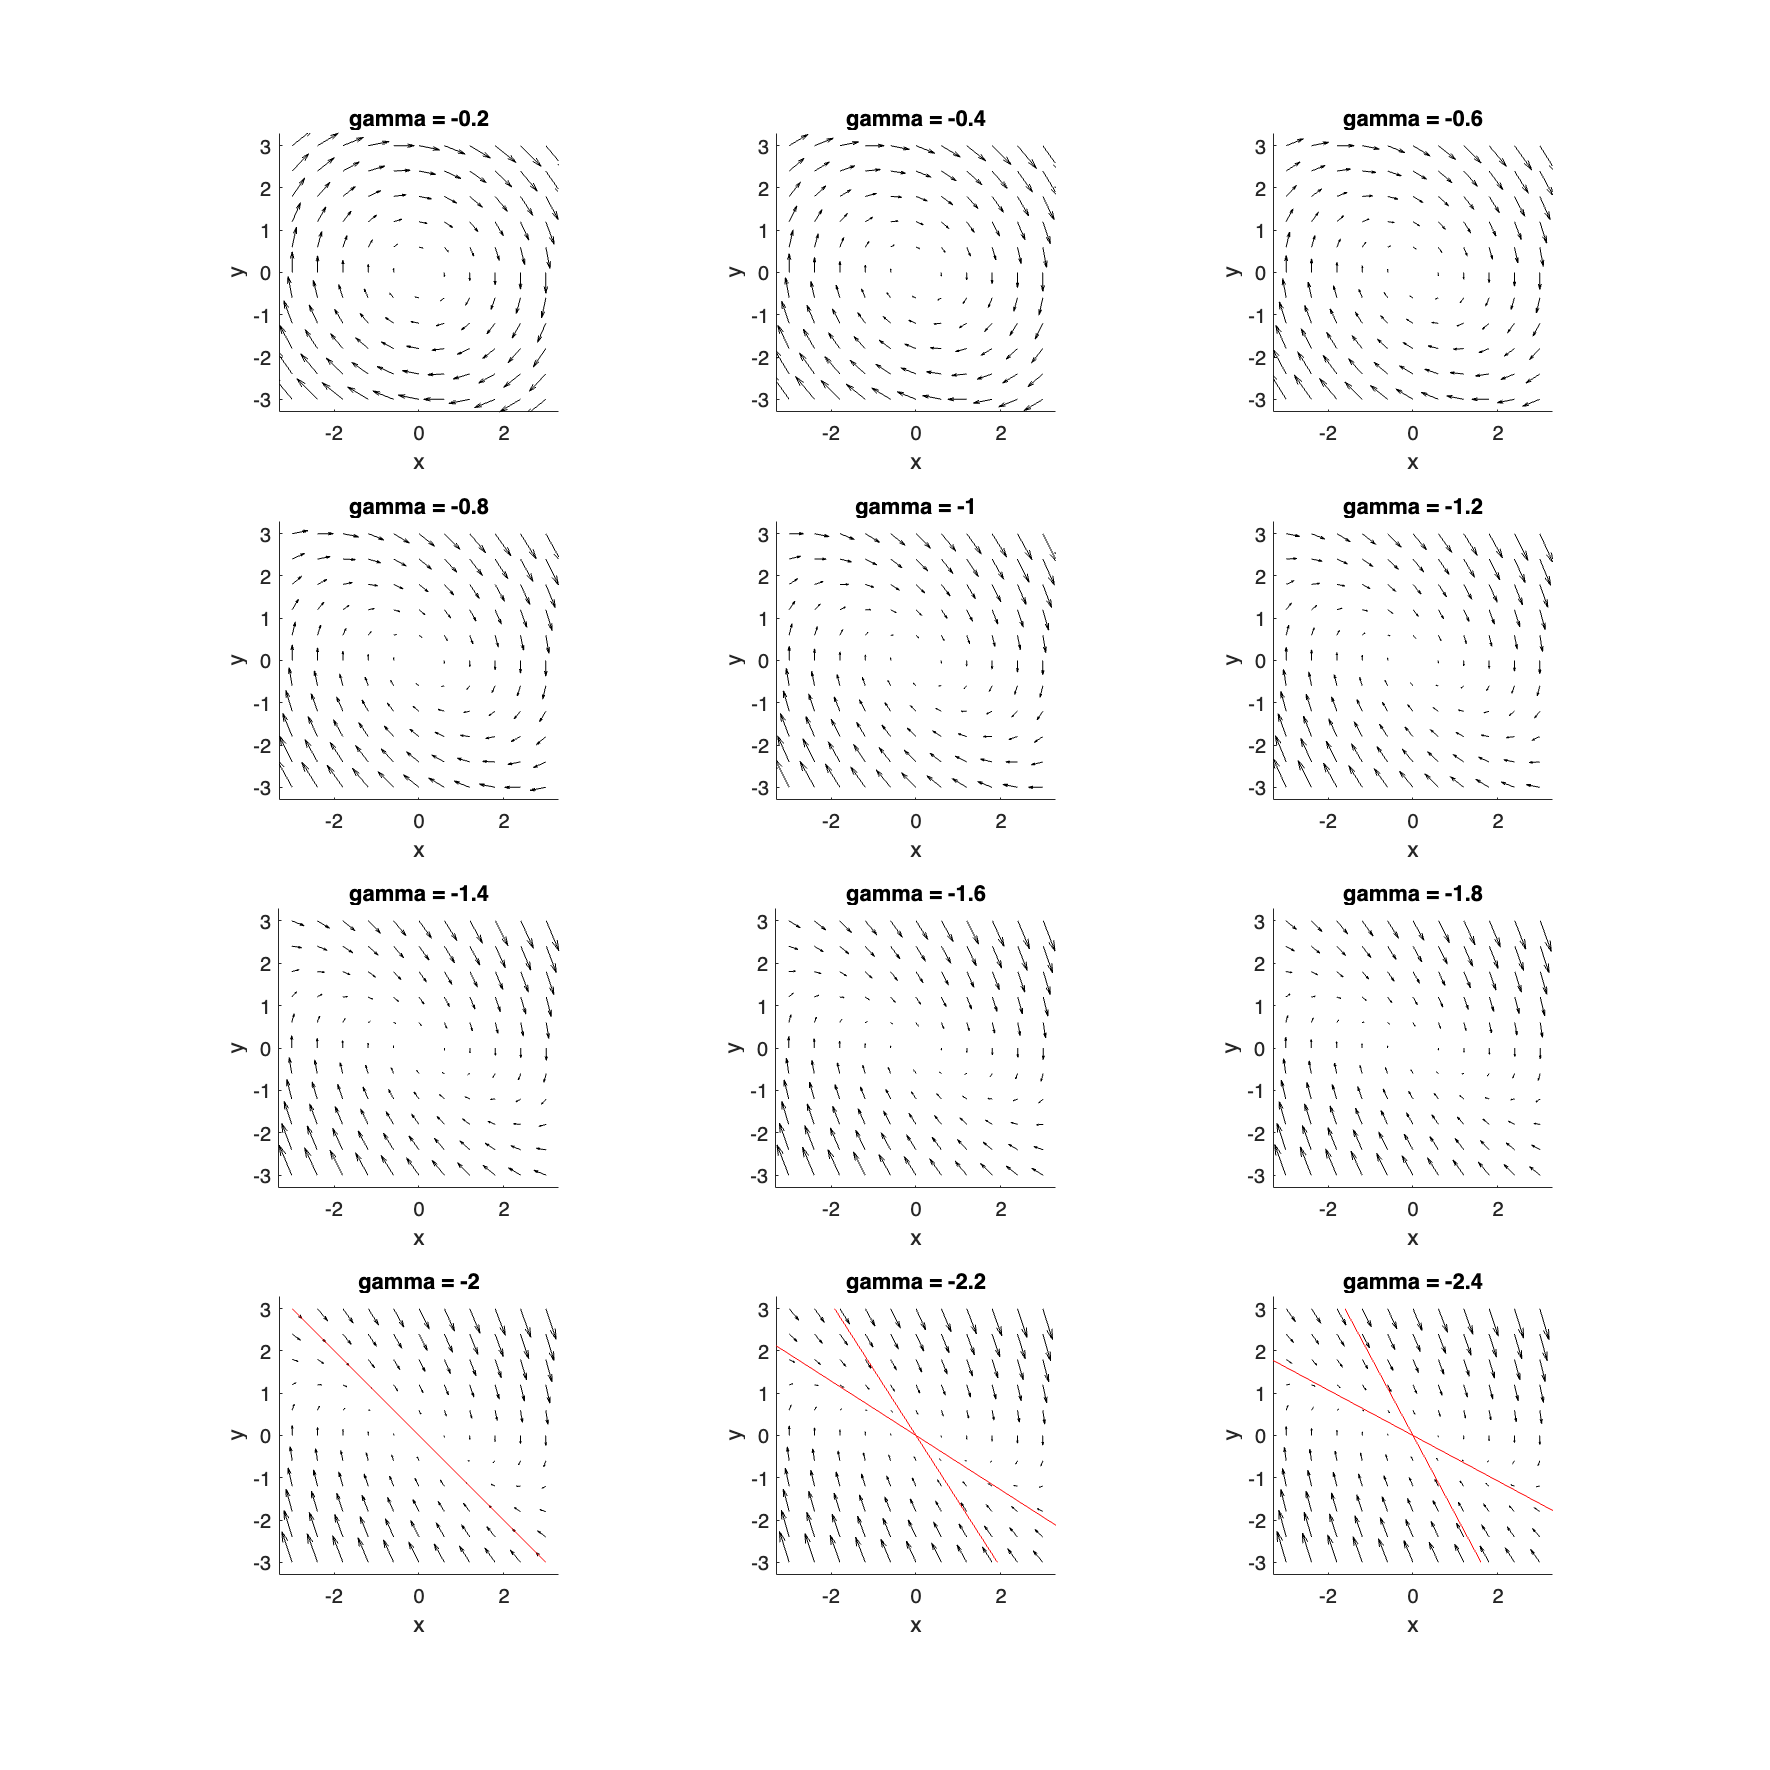


[y1,y2] = meshgrid([-3:0.6:3],[-3:0.6:3]);

% iterate over values of gamma; set gamma in A each time.
for gamma_idx=1:length(gamma_vals)
    
    % define the equation.
    A(2,2) = -1 * gamma_vals(gamma_idx);

    dy1dt = (A(1,1)*y1 + A(1,2)*y2);
    dy2dt = (A(2,1)*y1 + A(2,2)*y2);

    subplot(4, 3, gamma_idx);

    hold on;
    axis square
    quiver(y1, y2, dy1dt, dy2dt, 1, 'color', 'k');

    % plot eigenvectors.
    lamda1=0; lamda2=0;
    if det(A)<=(trace(A)^2)/4
        lamda1=(trace(A)+sqrt(trace(A)^2-4*det(A)))/2;
        lamda2=(trace(A)-sqrt(trace(A)^2-4*det(A)))/2;
        plot([-3*A(2,1)/(lamda1-A(2,2)) 3*A(2,1)/(lamda1-A(2,2))],[-3 3],'r-');
        plot([-3*A(2,1)/(lamda2-A(2,2)) 3*A(2,1)/(lamda2-A(2,2))],[-3 3],'r-');
    end

    xlabel('x');
    ylabel('y');
    title(['gamma = ' num2str(A(2, 2))]);
    set(gca,'xlim',1.1*[-3 3],'ylim',1.1*[-3 3]);
end